% The next two lines make your plots look better
set (0, 'DefaultAxesFontSize', 12) ;
set (0, 'DefaultLineLineWidth', 1.5) ;
n_arr = 0:200;
c_0 = 0.8;

x_arr = cos(pi .* n_arr / 3);
y_arr = zeros (1 , length(n_arr));
omega_0_arr = linspace(0, 1, 11)*pi;
max_arr = zeros(1, length(omega_0_arr));

for m_idx = 1:length(omega_0_arr)
    x_arr = cos (n_arr*omega_0_arr(m_idx)) ;
    y_arr = zeros (1, length(n_arr)) 
    for idx = 1:length(n_arr)
        if idx == 1
            y_arr(idx) = x_arr(idx);
        elseif idx == 2
            y_arr(idx) = x_arr(idx) + y_arr(idx - 1);
        else
            y_arr(idx) = x_arr(idx) + y_arr(idx - 1) - c_0*y_arr(idx-2);
        end
    end
    max_arr(m_idx) = max(y_arr);
end

y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_arr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


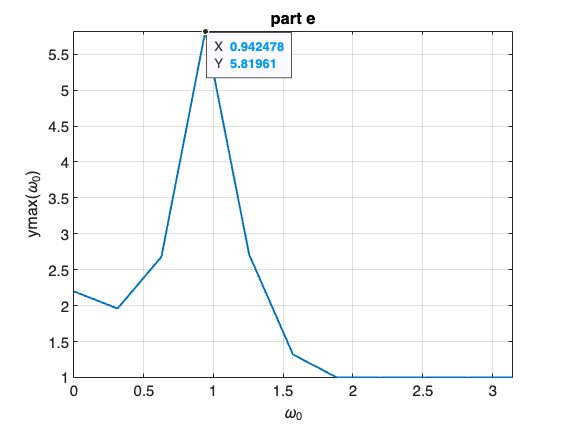


% You can use stem here , but it will be difficult to understand .
plot (omega_0_arr, max_arr);
title('part e', 'FontSize', 16)
xlabel('\omega_0', 'FontSize', 16);
ylabel('ymax(\omega_0)', 'FontSize', 16);

%% The next two lines make your plot look better
axis tight ;
grid on;